## Practical part

###  1. Applying features from Viola-Jones article

Our first try was to apply the feature that Viola and Jones obtained from the AdaBoost. We designed the Haar features on 24x24 pixel window like they did in the article. 

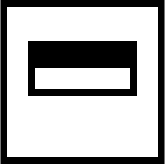      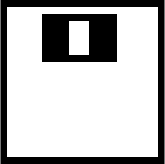

Then we apply them on picture while changing their sizes. The calculated value was stored in the matrix with the position for the top-left corner pixel. We calculated the intensity value of black and white area using integral image. Then substracted the black area from the white one and divided it by number of pixels of both areas. We calculated this value for both haar features and multiplied them so if one is big and another one as well, we get the best position of the face. This is what we obtained.

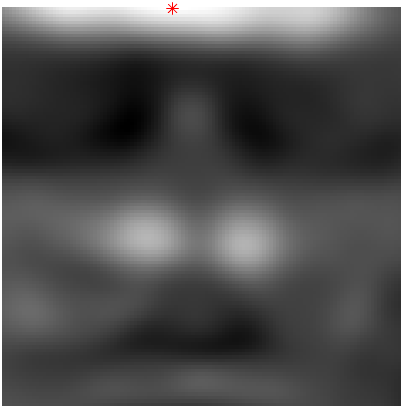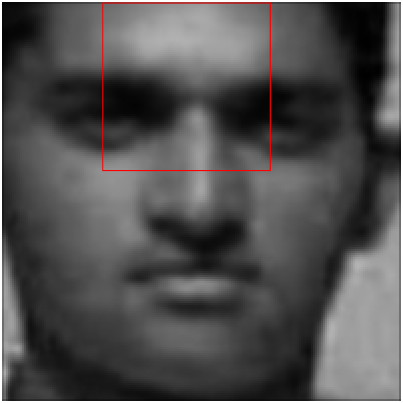

We figured that something is wrong because these haar features are calculating the intesity values, so fo example the first feature is showing us that the black area should be the dark area of the eyes and the white area should be light area of the cheecks. The darker the area of the eyes is, the smaller the intensity value should be. And the lighter the area of the cheeck is, the larger the intensity value is. But in our results we can see, that his forehead is lighter than the eyebrows so the calculated value should not be that white as we can see in (Fig. 3). What our problem was that, we were multiplying the numbers we obtained from both features. If both of the numbers were negative we got false positive values. So we changed the code and created a threshold for both features thats says that everything lower than 0 is 0. This way we obtained these results.

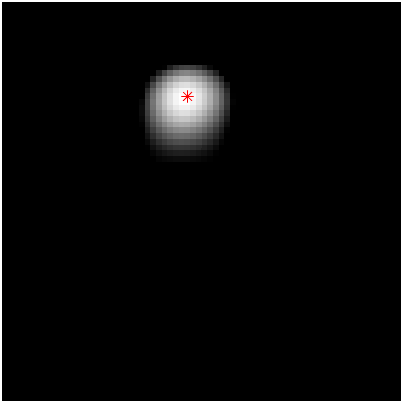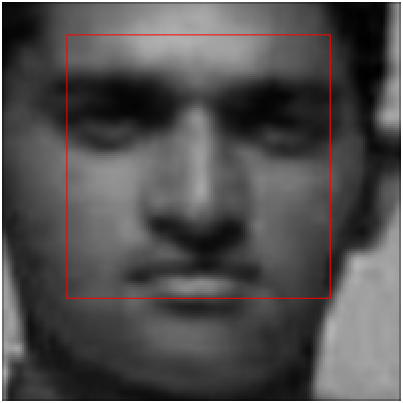

These results finally made sense but were not good enogh. When we tried to apply this to some other images these were the results we obtained.

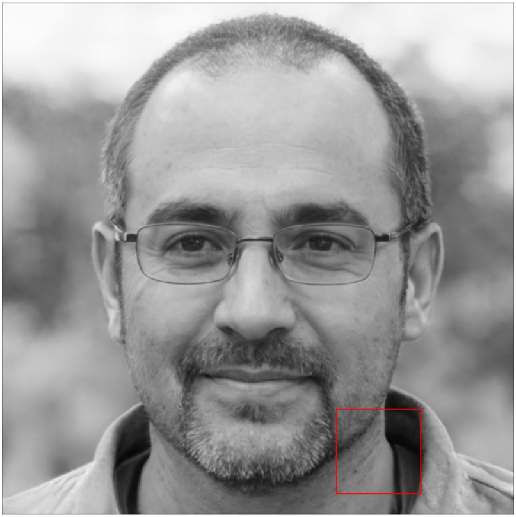 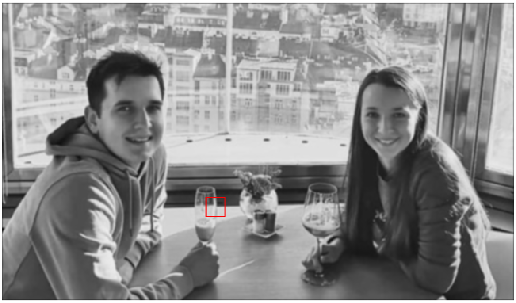 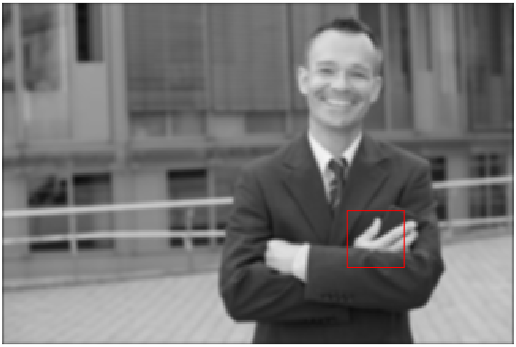

We need to look better at the close images what is happening.

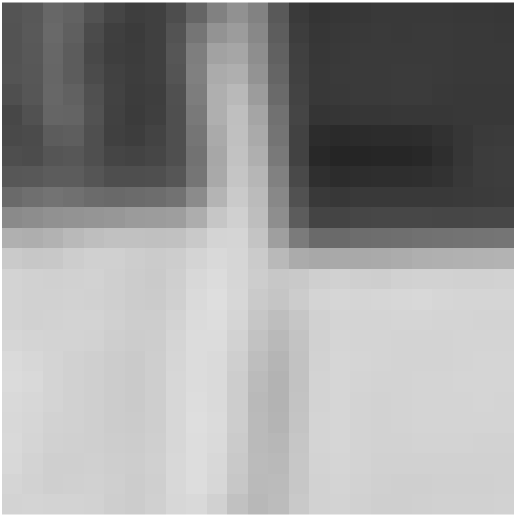      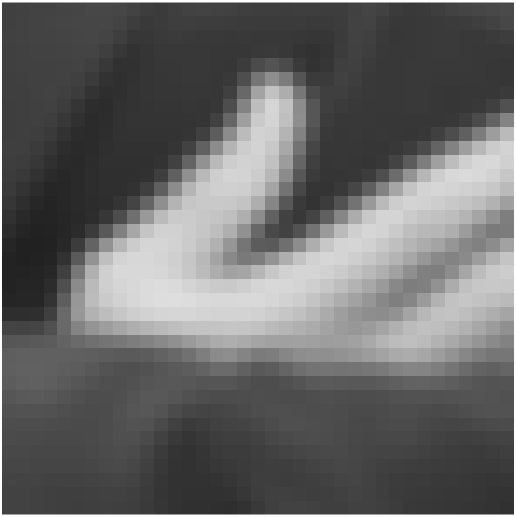      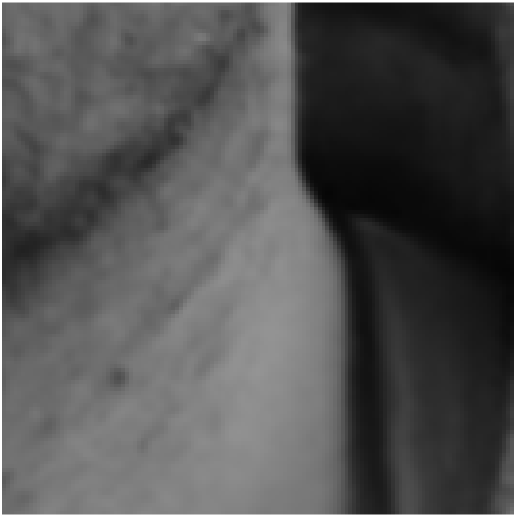

When we look at these croped images they all fullfill our two haar features. They all have upper part darker then lower at the place of our haar feature and also have a light vertical stripe in the middle. We understood that these two features are not enough. We tried to search for other features that should work, and also tried to see what is actually in Viola and Jones cascade detector but we couldn't find anything. So we decided to train our own features.

### Training Haar features

We found database of 19x19 pixel images with more than 2000 examples of face and non-face images. We can show a preview of some pictures from the database.

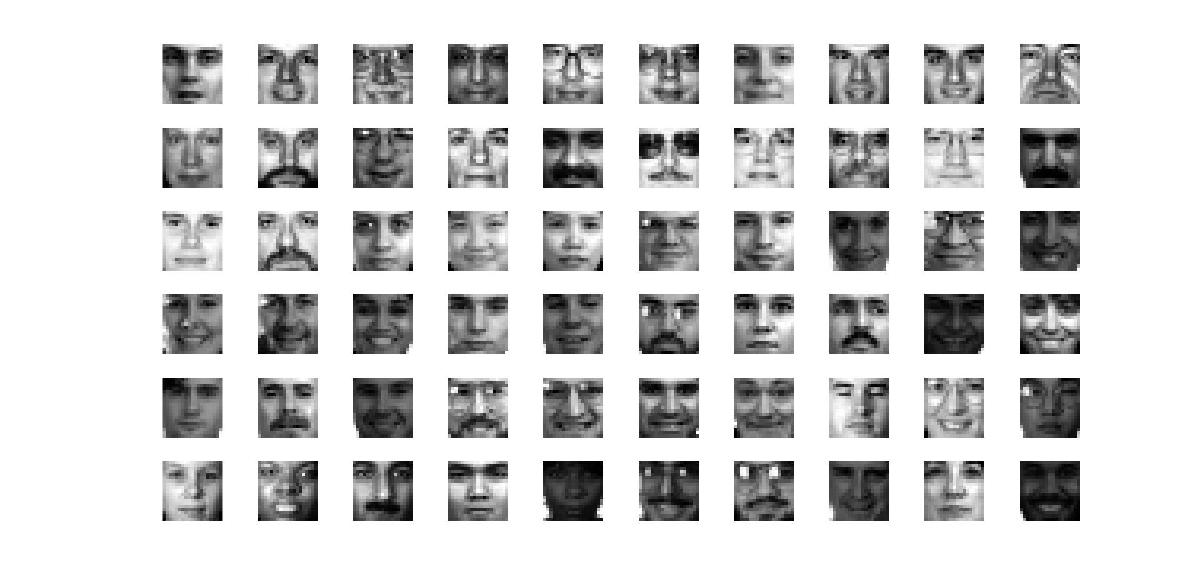

Figure. : Face images

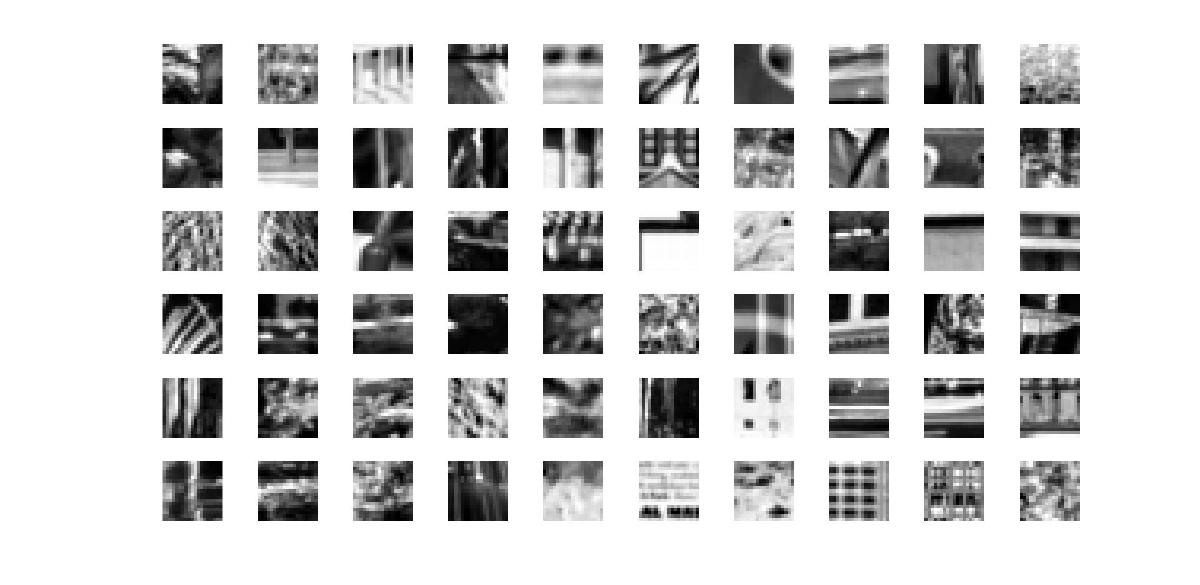

Figure. : Non-face images

### Calculating feature values

We created an algorithm that computes feature values for all sizes and 5 different tipes of haar features. This algorithm is written in matlab file *trainHaar.m. *We can explain how it works on the following code.

First we define on how many pictures we want to train our haar features.

% Number of training samples used
faceImages = 300;
nonFaceImages = 300;

Then we load the pictures and save them in separate databases.

fprintf(strcat('\nProcess: ***Training images inicialization***\n'))
% Loading face images
fprintf('Info: Loading face images.\n')
faceIIs = cell(1,faceImages);
for img = 1:faceImages
    image_path = ['TrainingFaces\',int2str(img),'.pgm'];
    I = imread(image_path);
    II = integralImage(I);
    faceIIs{img} = II;
end

% Loading non-face images
fprintf('Info: Loading non-face images.\n')
nonfaceIIs = cell(1,nonFaceImages);
for img = 1:nonFaceImages
    image_path = ['TrainingNonFaces\',int2str(img),'.pgm'];
    I = imread(image_path);
    II = integralImage(I);
    nonfaceIIs{img} = II;
end

Now we will inicialize our window size which is 19, because our training pictures. For faster but less precise training we can increase *haarSize *which multiplies the size of the haar features. 

% We found database with 19x19 pixel size images, it would be better to use
% 24x24 pixel images because of more compatible feature sizes. In our case
% we dont calculate feature value for last row or column of pixels in with
% certain features
window = 19;    % Training Image size
haarSize = 1;   % Haar feature size multiplier for faster computation

Then we define haar features which are shown on the pictures below. We can also set our *first_size* of the haar feature for faster training because we know that the small 2 pixel haar feature is not gonna be very robust.

                %  1    2    3    4    5
haars = haarSize*[1,2; 2,1; 1,3; 3,1; 2,2];
first_size =     [3,2; 2,3; 3,3; 3,3; 4,4]; % Small haars are not robust anyways

Types of Haar features

Then we define our variable *count *to count how many features we calculated and initialize our database for features and classifiers.

count = 0; % Feature count
featureDatabase = []; % To store calculated features
classifier = []; % To store Haar type and size

And we start calculating our feature values. For each size of the haar feature we calculate feature value for all face and non-face images so in the end we have number of features for each haar feature size same as the number images we used. We have programed our own function *calcHaarVal *to calculate the value for us. This function takes Integral image, haar type, pixel x and y and size of the haar feature in x and y direction.

% In this for cycle we calculate feature value of all posible sizes and all
% possible locations of haar feature
fprintf(strcat('\nProcess: ***Calculating Haar feature values started***\n'))
for haar = 1:5 % Calculatig features for all haar types
    fprintf(strcat('Info: Calculating features for Haar:',int2str(haar),'\n'))
    dimX = haars(haar,1);
    dimY = haars(haar,2);
    fsX = first_size(haar,1);
    fsY = first_size(haar,2);
    for pixelY = 1:1:window-dimY+1 % +1 because the Inegral image is one dimension bigger
        for pixelX = 1:1:window-dimX+1
            for haarY = fsY:dimY:window-pixelY+1
                for haarX = fsX:dimX:window-pixelX+1
                    % Counting number of features
                    count = count+1;
                   
                    % Calculating Feature value for face images
                    fvectorF = ones(faceImages,1);
                    for img = 1:faceImages
                        fval = calcHaarVal(faceIIs{img}, haar, pixelX, pixelY, haarX, haarY);
                        fvectorF(img) = fval;
                    end

                    % Calculating Feature value for non-face images
                    fvectorNF = ones(nonFaceImages,1);
                    for img = 1:nonFaceImages
                        fval = calcHaarVal(nonfaceIIs{img}, haar, pixelX, pixelY, haarX, haarY);
                        fvectorNF(img) = fval;
                    end
                    
                    % Creating calculated feature vector and database
                    fvector = [fvectorF;fvectorNF];
                    featureDatabase(:,count) = fvector;
                    % Saving Haar parameters for displayment
                    classifier = [classifier;pixelX,pixelY,haarX,haarY,haar];
                end
            end
        end
    end
    fprintf(strcat('Info: Number of features for Haar:',int2str(haar),' is :',int2str(count),'\n'))
end
fprintf(strcat('\nProcess: ***Calculating Haar feature values ended***\n'))

Now we have obtained our features and we can start calculating which of the features works the best using AdaBoost.

### AdaBoost

% Initialization of variables
numFValues = faceImages+nonFaceImages;  % Number of feature values
initialWeights = ones(numFValues,1)./(numFValues); % Initial weights are all the same
initialWeight = 1/(numFValues);                    % initial weight value
PvectorWeights = ones(faceImages,2);     % Positive vector weights are  1
NvectorWeights = -ones(nonFaceImages,2); % Negative vector weights are -1
topClassifiers = [];    % Our database where we save top 10 classifiers from each iteration

We have tried to explain everything in the code using comments and everything should be clear. In short words what our AdaBoost does is, that it takes the calculated feature values, for each size and type of the haar feature it sorts the feature values and calculates the threshold using Gini method where we take number between all of the features and see how it divided our values. Gini method looks at how many false positives and false negatives we have for each threshold and calculates Gini value. The threshold with lowest Gini value can separate the features the best. Then we take that threshold and divide our features with it again. We again calculate our Gini value that we now save. We don't have to do it again but it's clearer if we do. From all the Gini values with best threshold calculated for every size and type of feature we take the lowest again to see which type and size of haar feature could separate positive and negative samples. We store 10 best haar features to our topClassifier database. We take the best one and calculate the error it made. 


$$\mathrm{error}=\mathrm{initial}\;\mathrm{weight}\cdot \left(\mathrm{false}\;\mathrm{positives}+\mathrm{false}\;\mathrm{negatives}\right)$$


Then using the formula:


$$\mathrm{Amount}\;\mathrm{of}\;\mathrm{Say}=\frac{1}{2}\cdot \log \left(\frac{1-\mathrm{error}}{\mathrm{error}}\right)$$


Using this Amount of Say we put create new weights where we put more weight to the wrongly classified features. Then we divide them by the sum of new weights so the sum of them would be one. With these new weights we create a new set of feature values where we put more wrongly inclassified features into the feature value database and we repeat the process. We consider that now we have calculated new feature values and we set the same initial weight as before. This is repeated by the number of iterations we set.

% Number of adaboost iterations
iterations = 50;
for stemps = 1:iterations
    fprintf(strcat('Info: Iteration:',int2str(stemps),'\n'))
    % For calculated feature values of each haar feature applied on our 
    % training images we are gonna find the best threshold for each haar 
    % feature and then calculate the Gini index. Then we find the lowest
    % Gini index which represents haar feature that could classifi the
    % sample values with least amount of incorrectly classified samples.
    for f = 1:size(featureDatabase,2)
        fvector = [PvectorWeights;NvectorWeights]; % This vector has 2 columns, second will be the sign
        fvector(:,1) = featureDatabase(:,f);       % In the fisrt column we put our calculated values
        [~, order] = sort(fvector(:,1));           % We get the order in which we should sort them
        fsorted = fvector(order,:);                % And we sort the calculated values
        avg = zeros(size(fsorted,1),1);     % Initialize our vector for threshold value
        GiniThreshold = zeros(size(fsorted,1)-1,1); % and also vector for Gini value
        
        % Calculating threshold
        for t = 1:size(fsorted,1)-1
            avg(t) = (fsorted(t,1)+fsorted(t+1,1))/2;  % Average between 2 neighbour features
            lower = (fsorted(:,1)<avg(t)).*fsorted;    % Features lower than calculated avg
            higher = (fsorted(:,1)>avg(t)).*fsorted;   % Features higher than calculated avg
            lowP = length(find(lower(:,2)==1));     % False negative features
            lowN = length(find(lower(:,2)==-1));    % True negative features
            highP = length(find(higher(:,2)==1));   % True positive features
            highN = length(find(higher(:,2)==-1));  % False positive features
            GiniThreshold(t) = Gini(lowP,lowN,highP,highN);
        end
        % We find the lowest Gini value which is the number that
        % best separates positive and negative samples
        threshold = avg(GiniThreshold==min(GiniThreshold));
        if length(threshold)>1;threshold = threshold(1);end
        % Separating features using this threshold
        lower = (fsorted(:,1)<threshold).*fsorted;    % Features lower than calculated avg
        higher = (fsorted(:,1)>threshold).*fsorted;   % Features higher than calculated avg
        lowP = length(find(lower(:,2)==1));     % False negative features
        lowN = length(find(lower(:,2)==-1));    % True negative features
        highP = length(find(higher(:,2)==1));   % True positive features
        highN = length(find(higher(:,2)==-1));  % False positive features
        
        GiniError(f,1) = Gini(lowP,lowN,highP,highN);
        GiniError(f,2) = threshold;
    end
    % Saving 10 best classifiers from each iteration
    [~, order] = sort(GiniError(:,1));
    topOrder = order(1:10);
    topClassifiers = [topClassifiers;classifier(topOrder,:),GiniError(topOrder,2)];
    
    % We don't need to calculate new weights if this is the last iteration
    if stemps == iterations
        fprintf(strcat('\nProcess: ***Finished Adaboost***\n'))
        break
    end

    % Minimal Gini value or haar feature that has least number of incorrectly
    % classified samples
    minGiniVal = min(GiniError(:,1)); 
    minGiniPos = find(GiniError(:,1)==minGiniVal); % Position in Database
    minGiniPos = minGiniPos(1); % If there is multiple positions of min value
    threshold = GiniError(minGiniPos,2); % Taking already calculated threshold
    
    % For better memory we calculate it one again and we don't store all
    % calculated values for each feature
    fvector = [PvectorWeights;NvectorWeights];
    fvector(:,1) = featureDatabase(:,minGiniPos(1)); % features of best classifier
    [~, order] = sort(fvector(:,1));
    fsorted = fvector(order,:); % sorted features of best classifier
    
    % Separating features using this threshold
    lower = (fsorted(:,1)<threshold(1)).*fsorted;    % Features lower than calculated avg
    higher = (fsorted(:,1)>threshold(1)).*fsorted;   % Features higher than calculated avg
    lowP = length(find(lower(:,2)==1));     % False negative features
    lowN = length(find(lower(:,2)==-1));    % True negative features
    highP = length(find(higher(:,2)==1));   % True positive features
    highN = length(find(higher(:,2)==-1));  % False positive features
    % Positions of incorrectly classified samples
    incorrectPos = [find(lower(:,2)==1);find(higher(:,2)==-1)];
    
    % Calculating Amount of Say for each weight
    error = initialWeight*(lowP+highN);
    if error==1; error=1.01; end
    AoS = 0.5*log((1-error)/error); % Amount of Say 
    % Weight multiplier
    multiplier = ones(faceImages+nonFaceImages,1);
    multiplier(:,1) = exp(-AoS);
    multiplier(incorrectPos,1) = exp(AoS);
    % New weights
    neweights = initialWeights.*multiplier;
    neweights = neweights/sum(neweights);
    
    % Creating new collection of stamples
    cum = cumsum(neweights);
    newOrder = ones(numFValues,1);
    for w = 1:numFValues
        between = 0;
        rnd = rand;
        wn = 1;
        while between == 0
            if rnd<cum(wn)
                between = 1;
                newOrder(w) = wn;
            else
                wn = wn+1;
            end
        end
    end
    featureDatabase = featureDatabase(newOrder,:);
end

In the end we save our top classifiers so we can work with them.

save topClassifiers topClassifiers

### Obtained Haar features

These are the results we obtained when using 300 face images and 300 non-face images with 50 adaboost iterations. We display best haar feature from each iteration with their threshold on top.

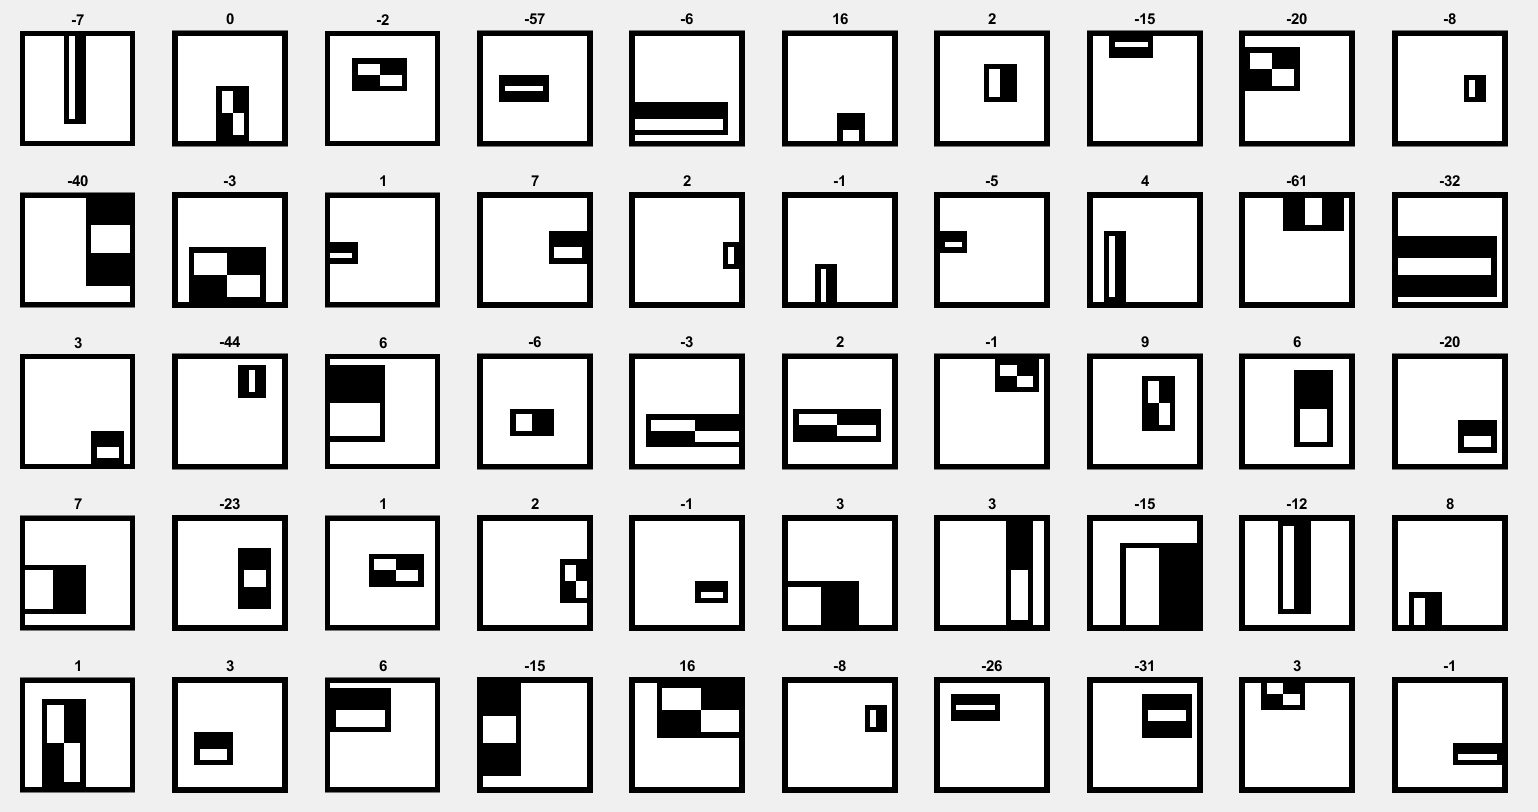

We can see that some of the features we obtained are similar to the ones Viola and Jones obtained in their article. The results are dependent on the training images as well as how the new features are created in AdaBoost. Now we can try to apply some of the features we got to create our own cascade and detect images.

### Face Detection

To apply face detection we created new matlab file called *detectFaces. *In this matlab script we have written an algorithm that slides the haar feature window over every possible area and resizes it to the maximum size as well. When we apply our window, we call our cascade function which calculates the values of applied haar features and gives us 0 when it did not detect a face and some value when its possible that we have found the face.

% Loading our image database
images = 20;

fprintf('Process: Loading images.\n\n')
% Initializing databases
Is = cell(1,images);
IIs = cell(1,images);
for img = 1:images
    image_path = ['images\',int2str(img),'.jpg'];
    I = imread(image_path);
    Ig = im2gray(I);
    % Filtering image
    gaussian = fspecial('gaussian',5,1);
    Ig = imfilter(Ig,gaussian);
    % Creating image database
    Is{img} = Ig;   % Gray scale images
    II = integralImage(Ig); % Calculating Integral image
    IIs{img} = II;  % Integral images
end

% Initial size of the haar feature
start_haar = 24;
haarSize = 1;

% Initializing croped faces database
crop = {};
%
% Detection for all images in database
fprintf(strcat('Process: Starting with detection\n'))
for img = 1:images
    fprintf(strcat('Info: Detecting faces on image:',int2str(img),'\n'))
    I_features = {};    % We create a new DB for features for every img
    [row,col] = size(Is{img});    % Size of the image
    maxsize = floor(min([row/24,col/24]));  % Max size for haar feature
    hsize = 0;      % We initialize haar size 
    window = [];    % window is our haar feature size
    for haarSize = 1:0.5:maxsize % Every iteration we make window larger by 0.5
        hsize = hsize+1;    % Counting window changes
        window(hsize) = floor(haarSize*start_haar); % Changing window size
        % Initialize matrix for calculated haar values
        fval = zeros(row-window(hsize)+1,col-window(hsize)+1);
        for i = 1:row-window(hsize)+1       % +1 pixel because we
            for j = 1:col-window(hsize)+1   % substracted it
                fval(i,j) = ourCascade(IIs{img}, haarSize, i, j);
            end
        end
        % Saving feature matrix for each size of the haar feature
        I_features{hsize} = fval;
    end
    
    % Finding the best macth
    bestmatch = []; % Inicialization
    % For every size of the feature we find the highest value
    for f=1:length(I_features)
        bestmatch(f) = max(max(I_features{f})); % Save the highest value
        if bestmatch(f)==0  % if there is no match
            i(f)=0; % We set the coordinates to 0 just to fill matrix
            j(f)=0;
        else    % We save the original coordinates of the highest value 
            [i(f),j(f)] = find(I_features{f}==bestmatch(f));
        end
    end
    % Finding the best from all sizes of the window
    best = max(bestmatch);
    p = find(bestmatch==best);
    p = p(1); % if there is multiple best findings

    % Croping the detected window from the image if we find the face
    if i(p)==0 && j(p)==0
        fprintf(strcat('Info: Could not find a face in image:',int2str(img),'\n'))
    else
        crop = imcrop(Is{img},[j(p),i(p),window(p),window(p)]);
        Filename = sprintf('crop%d.jpg',img);
        save(['C:\1. Škola\1.semester(ERASMUS)\CV\Short_project\MyDetector\cropedFaces\' Filename],"crop")

        % Plotting results with map, image with bounding box and croped image
%         figure
%         subplot(2,2,1), imshow(I_features{p},[]), hold on
%         subplot(2,2,1), plot(j(p),i(p),'r*'), hold off
%         subplot(2,2,3), imshow(Is{img})
%         subplot(2,2,3), rectangle('Position',[j(p),i(p),window(p),window(p)],'EdgeColor','r')
%         subplot(2,2,4), imshow(crop)

        % Plotting only image and bounding box
%         subplot(1,3,img), imshow(Is{img})
%         subplot(1,3,img), rectangle('Position',[j(p),i(p),window(p),window(p)],'EdgeColor','r')
        
        % Plotting all croped images 
        subplot(1,3,img), imshow(crop)
    end
end


### Conclusion

For our short project which was to design an implementation of a face detection and location technique to crop faces from human images DB, we have done the following:

We were trying to use Viola-Jones algorithm to detect faces in our images. Using only the two features from their article we obtained good results for very simple face images. For comlicated images we found areas that correspond to the haar features but, those areas were not the faces.

In order to find out which another haar features we should use we tried to train our own haar features. We found a database of 19x19 pixels face and non-face images. We created an algorithm to calculate feature values for all the possible sizes and for five different types of haar features. We calculated feature values for 300 face images and 300 non-face images. After that we applied AdaBoost learning algorithm to obtain better haar features. We obtained some features that were similar to the features that Viola and Jones obtained but it really depends our training images and also creation of new feature values in adaboost. The best haar features and their threshold are in Fig. ?????????.

The last step was trying different haar features and creating our cascade. We found out that the haar features that Viola-Jones obtained work well in the first 2 cascades, eliminating a lot of areas without faces. Then we were trying to create smalle features from these two, to detect righ eye, left eye and also the mouth. We tried to apply some haar features that we obtained from AdaBoost. We were also trying to change the threshold but it is very complicated to see the difference. In the end we did not found an optimal solution to find faces in complicated images. For images with just faces its okay. For images that have a complicated background we did not obtain any good results. We tried to change the initial size of the haar feature which worked well, but its complicated to change a size according to the size of the image, when the image can be small with just a face and have a lot of pixels or it can be big with a lot of faces but with less pixels.

What we think that we should do is try to train AdaBoost with more positive and negative images and obtain better results. Also these images should be a very good dataset and with even number of pixels in order to have more possible sizes of haar feature. Then try as many possible options of haar cascades as possible to obtain good results. This is very hard and complicated trial and error task, and maybe its possible to create an algorithm as well, with already good faceDetector to check if the result is positive or negative.